# Honours Live Script 10

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
 end

## Save Data

 if exist("workspaceVarHonours", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabHonours.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Final Experiments: Base MPT, Random, and Empty

Examining Results: Base MPT, Random, and Empty

Testing Larval Contribution Code (and Mean/Final Code Too)

Final Experiments: Larval Contribution MPT, Mean and Recent Historical Values

## Assumptions Made

% I don't think I need to rezone to 80 reefs anymore, 100 seems to be fine

## Notes

% I mucked about with the order of the arguments in the boxplot code, so
% that might fuck some earlier scripts a bit whoops

## Final Experiments: Base MPT, Random, and Empty

% REMOVE THIS LATER - just for testing
simStructFinTest = simStructFin;

simStructFinTest.mpaSeqs = simStructFin.mpaSeqs(1:5);
simStructFinTest.obsSeqs = simStructFin.obsSeqs(1:5);
simStructFinTest.warmupSeqs = simStructFin.warmupSeqs(1:5);

% need to write the code in a sequential form first, check if it works, and
% then run it in parallel afterwards
methodStruct.methodInd = "MPTBiom";
methodStruct.meanVarWeight = 0.75;
simOutTest = runMPASimulation(simStructFinTest, areaStructSwains, areaStructGBR, ...
    specStructCT, randStructFin, actionStructFin, methodStruct)

% note that running all of the experiments below took 40 hours total

% run the experiment for the Swains region

% ensure parallel processes are cancelled
if exist('futureVecFinSwains', 'var')
    cancelFutureVec(futureVecFinSwains);
    clear futureVecFinSwains
end

% run in parallel
methodStringVec = ["random", "none", "MPTBiom", "MPTBiom", ...
    "MPTBiom", "MPTBiom", "MPTBiom"];
weightVec = [0, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:7
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinSwains(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructSwains, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 14 workers.


% extract results
% if checkFutureVec(futureVecFinSwains)
%     for i = 1:7
%         simOutCellSwains{i} = fetchOutputs(futureVecFinSwains(i));
%     end
%     clear futureVecFinSwains
% end

Futures have completed succesfully.


% run the experiment for the Towns region

% ensure parallel processes are cancelled
if exist('futureVecFinTowns', 'var')
    cancelFutureVec(futureVecFinTowns);
    clear futureVecFinTowns
end

% run in parallel
methodStringVec = ["random", "none", "MPTBiom", "MPTBiom", ...
    "MPTBiom", "MPTBiom", "MPTBiom"];
weightVec = [0, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:7
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinTowns(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructTowns, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
% if checkFutureVec(futureVecFinTowns)
%     for i = 1:7
%         simOutCellTowns{i} = fetchOutputs(futureVecFinTowns(i));
%     end
%     clear futureVecFinTowns
% end

Futures have completed succesfully.


% run the experiment for the North region

% ensure parallel processes are cancelled
if exist('futureVecFinNorth', 'var')
    cancelFutureVec(futureVecFinNorth);
    clear futureVecFinNorth
end

% run in parallel
methodStringVec = ["random", "none", "MPTBiom", "MPTBiom", ...
    "MPTBiom", "MPTBiom", "MPTBiom"];
weightVec = [0, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:7
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinNorth(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructNorth, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
% if checkFutureVec(futureVecFinNorth)
%     for i = 1:7
%         simOutCellNorth{i} = fetchOutputs(futureVecFinNorth(i));
%     end
%     clear futureVecFinNorth
% end

Futures have completed succesfully.


% to avoid being a fucking moron I'm gonna save the current results I have
% in a separate .mat file
save firstSetResults simOutCellTowns simOutCellSwains simOutCellNorth ...
    simStructFin

## Examining Results: Base MPT, Random, and Empty

% let's look at the results now

% maybe quickly as a bit of a sanity check, let's ensure that the
% constraints are always met
ctr = 0;
shitVec = [];
for i = 1:length(simOutCellSwains)
    for j = 1:length(simOutCellSwains{i}.mpaSel)
        if simOutCellSwains{i}.mpaSel{j} * areaStructSwains.areas ...
                > simStructFin.resources * sum(areaStructSwains.areas)
            shitVec = [shitVec, simOutCellSwains{i}.mpaSel{j} ...
                * areaStructSwains.areas / sum(areaStructSwains.areas)];
            ctr = ctr + 1;
        end
        if simOutCellTowns{i}.mpaSel{j} * areaStructTowns.areas ...
                > simStructFin.resources * sum(areaStructTowns.areas)
            shitVec = [shitVec, simOutCellTowns{i}.mpaSel{j} ...
                * areaStructTowns.areas / sum(areaStructTowns.areas)];
            ctr = ctr + 1;
        end
        if simOutCellNorth{i}.mpaSel{j} * areaStructNorth.areas ...
                > simStructFin.resources * sum(areaStructNorth.areas)
            shitVec = [shitVec, simOutCellNorth{i}.mpaSel{j} ...
                * areaStructNorth.areas / sum(areaStructNorth.areas)];
            ctr = ctr + 1;
        end
    end
end
ctr

ctr = 1

shitVec

shitVec = 0.3300

max(shitVec)

ans = 0.3300

max(shitVec - 0.33)

ans = 1.0531e-09


% ok, so the constraints are only violated by like roundoff error, I think
% I can live with that but I'm glad I checked

% just realised my yearly connectivity matrices are using full storage
% which is probably why my workspace is cooked, so let's fix that
for i = 1:length(conMatsCTYearly)
    conMatsCTYearly{i} = sparse(conMatsCTYearly{i});
end
aveConMatCT = sparse(aveConMatCT);

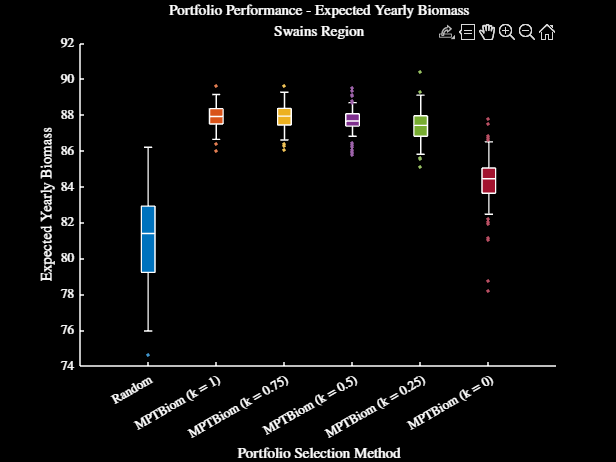

% now, plot the results for the retroactive and future approaches
var1 = [1, 3:7];
figure
plotMethodPerf(simOutCellSwains(var1), "expVal", "Swains")
darkFig()

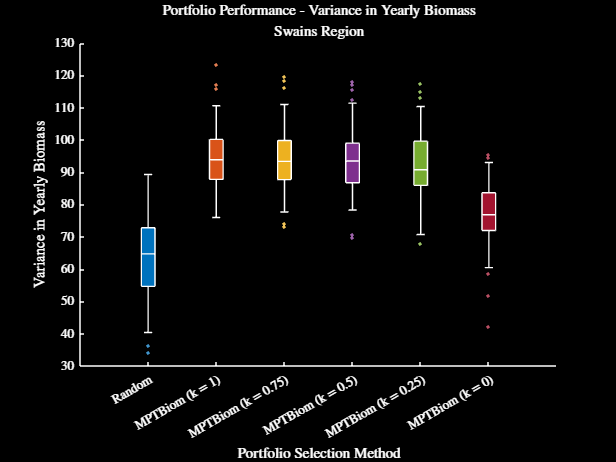

figure
plotMethodPerf(simOutCellSwains(var1), "var", "Swains")
darkFig()

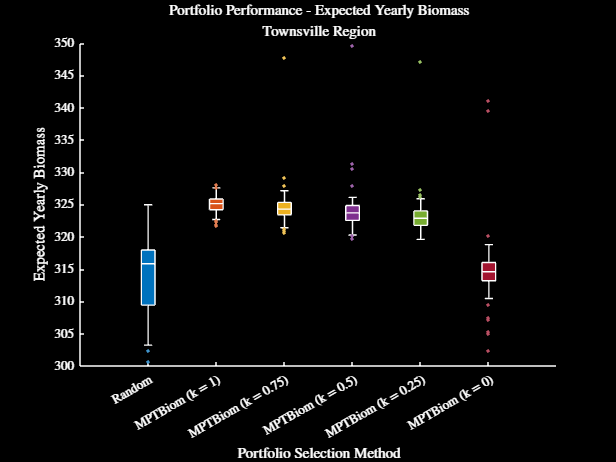

figure
plotMethodPerf(simOutCellTowns(var1), "expVal", "Townsville")
darkFig()

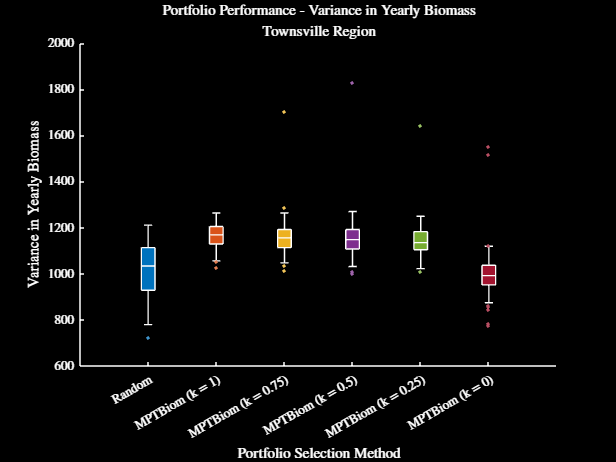

figure
plotMethodPerf(simOutCellTowns(var1), "var", "Townsville")
darkFig()

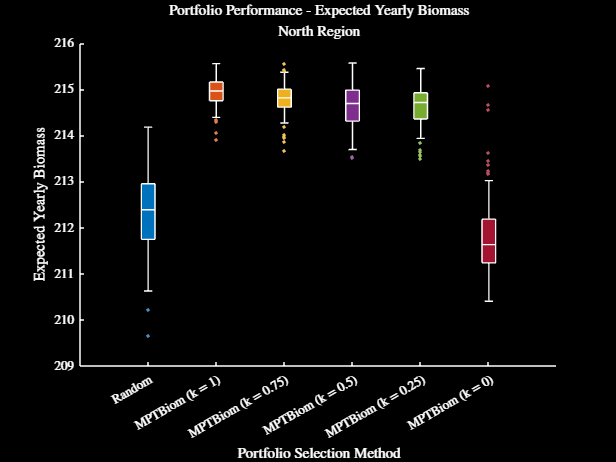

figure
plotMethodPerf(simOutCellNorth(var1), "expVal", "North")
ylim([209, 216])
darkFig()

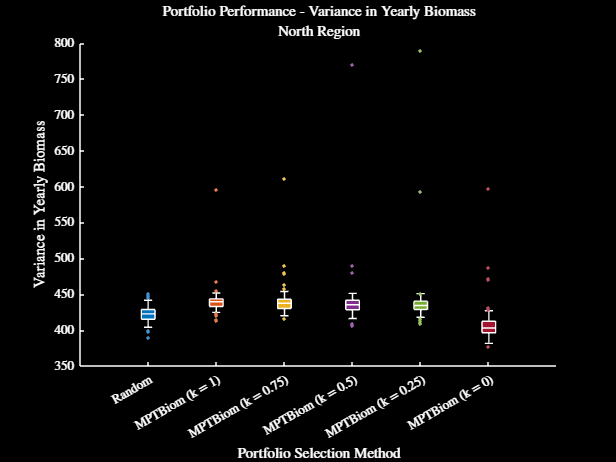

figure
plotMethodPerf(simOutCellNorth(var1), "var", "North")
darkFig()

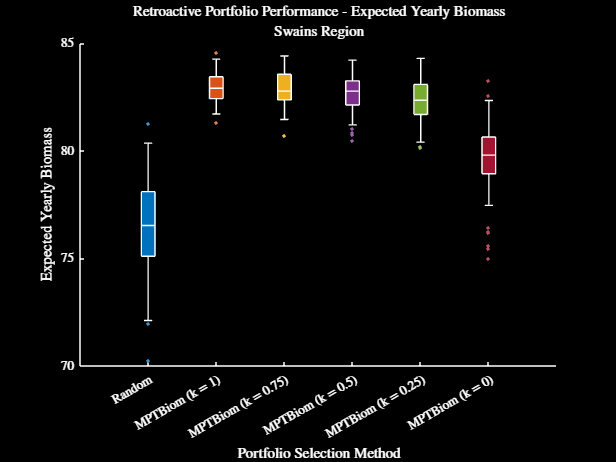

% look at the retroactive performance
var1 = [1, 3:7];
figure
plotMethodPerf(simOutCellSwains(var1), "expValRetro", "Swains")
darkFig()

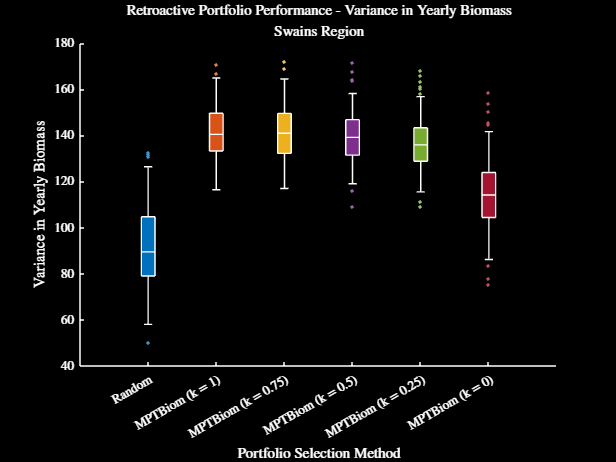

figure
plotMethodPerf(simOutCellSwains(var1), "varRetro", "Swains")
darkFig()

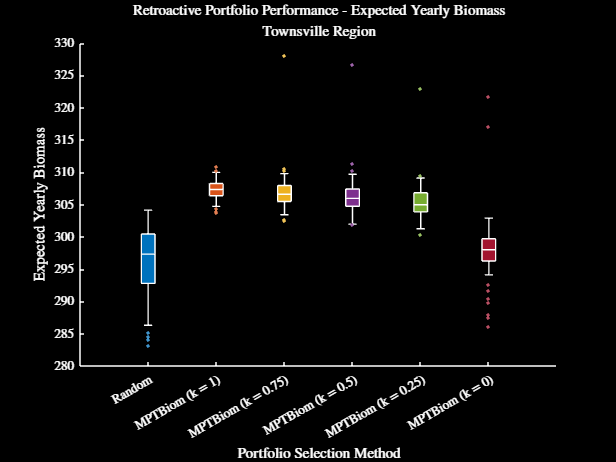

var1 = [1, 3:7];
figure
plotMethodPerf(simOutCellTowns(var1), "expValRetro", "Townsville")
darkFig()

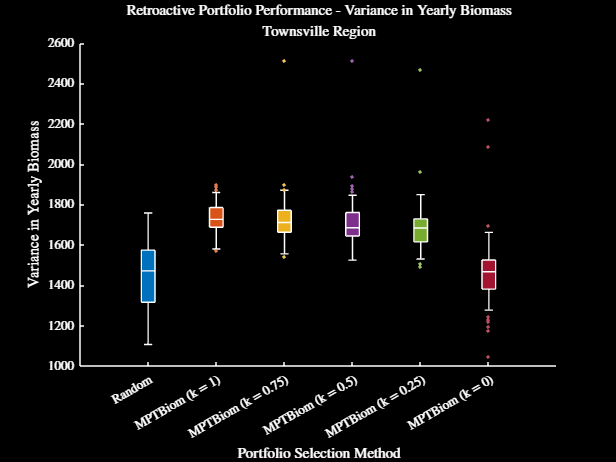

figure
plotMethodPerf(simOutCellTowns(var1), "varRetro", "Townsville")
darkFig()

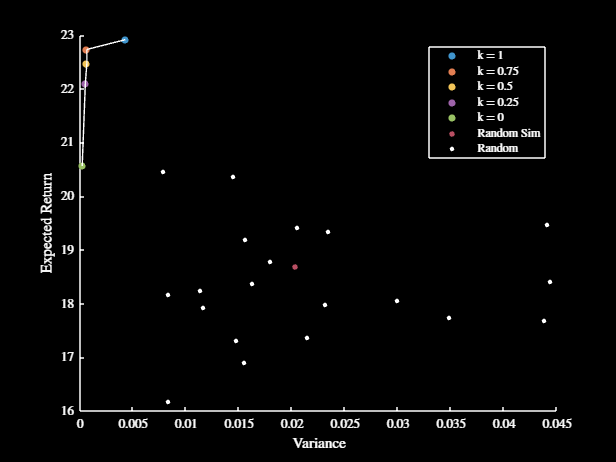

% check the decision spaces
var1 = 3;
figure
plotMPADecSpace(simStructFin, areaStructSwains, areaStructGBR, ...
    specStructCT, randStructFin, simOutCellSwains, var1)
darkFig()

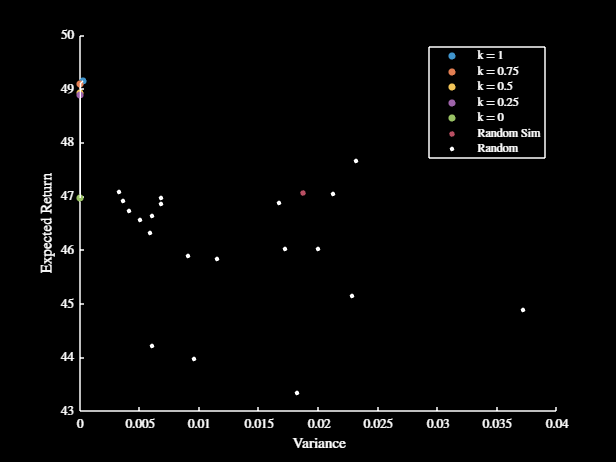

figure
plotMPADecSpace(simStructFin, areaStructNorth, areaStructGBR, ...
    specStructCT, randStructFin, simOutCellNorth, var1)
darkFig()

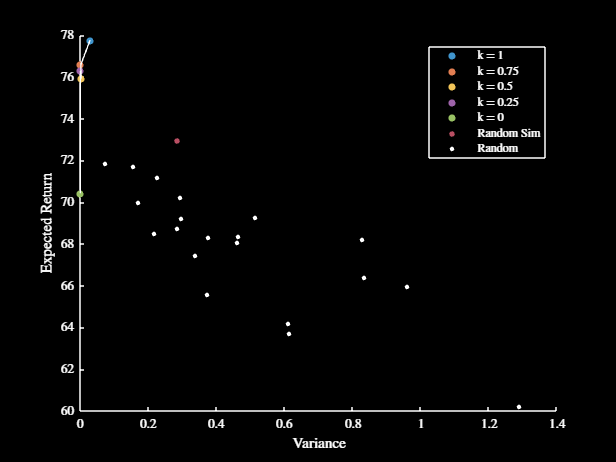

figure
plotMPADecSpace(simStructFin, areaStructTowns, areaStructGBR, ...
    specStructCT, randStructFin, simOutCellTowns, var1)
darkFig()

% check the exit flags
var1 = [];
for i = 3:length(simOutCellSwains)
    var1 = [var1; simOutCellSwains{i}.exitFlag; ...
        simOutCellTowns{i}.exitFlag; simOutCellNorth{i}.exitFlag];
end
var1;
sum(var1 == 1)

ans = 1500

% can also look at heatmaps - it's entirely possible that it's just that
% the same reefs are being chosen every time across methods, which accounts
% for the similarity in results
figure
plotOverlapProps(simOutCellSwains, 3:7, "Swains")
darkFig()

figure
plotOverlapProps(simOutCellTowns, 3:7, "Townsville")
darkFig()

figure
plotOverlapProps(simOutCellNorth, 3:7, "North")
darkFig()

% nothing too worrying with the heatmaps, let's also look at the
% frequencies
figure
plotSelectionHeatmap(simOutCellSwains, 3:7, "Swains", GBRShapeSwains, ...
    "frequency")
figResize(1.75, 1.2)
darkFig()

figure
plotSelectionHeatmap(simOutCellTowns, 3:7, "Towns", GBRShapeTowns, ...
    "frequency")
figResize(1.75, 1.2)
darkFig()

figure
plotSelectionHeatmap(simOutCellNorth, 3:7, "North", GBRShapeNorth, ...
    "frequency")
darkFig()
figResize(1.75, 1.2)

% wanna quickly check the years and dates for the COTS matrices
SLIMCellDailyNames

SLIMCellDailyNames = 30×1 string array
    "01_12_2018"
    "07_12_2018"
    "14_12_2018"
    "21_12_2018"
    "28_12_2018"
    "01_01_2019"
    "07_01_2019"
    "14_01_2019"
    "21_01_2019"
    "28_01_2019"
    "01_12_2019"
    "07_12_2019"
    "14_12_2019"
    "21_12_2019"
    "28_12_2019"
    "01_01_2020"
    "07_01_2020"
    "14_01_2020"
    "21_01_2020"
    "28_01_2020"
    "01_12_2020"
    "07_12_2020"
    "14_12_2020"
    "21_12_2020"
    "28_12_2020"
    "01_01_2021"
    "07_01_2021"
    "14_01_2021"
    "21_01_2021"
    "28_01_2021"


## Testing Larval Contribution Code (and Mean/Final Code Too)

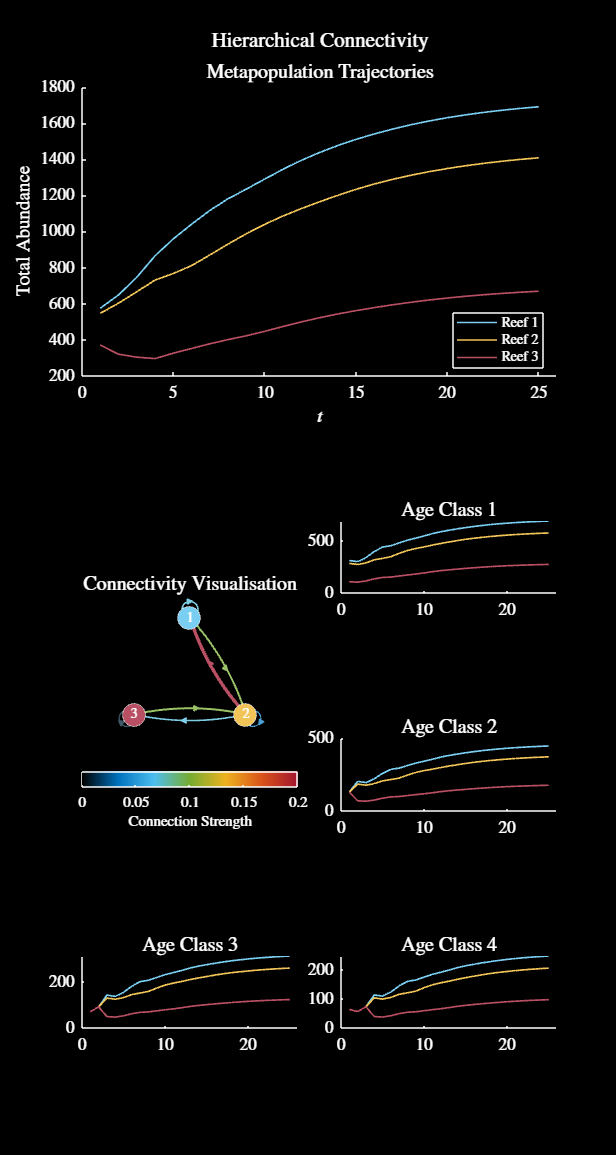

% want to test here my code that decides the larval contribution of each
% reef here

% let's do this based on the heirarchical connectivity example, so that I
% can clearly see what is going on
% alter the self recruitment levels
tMax = 25;
conMat = [0.07, 0.1, 0; ...
    0.2, 0.04, 0.07; ...
    0, 0.1, 0.01];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "Hierarchical Connectivity", "Interpreter", 'L')
setFontSize(14)
darkFig(tL)
figResize(2.5)

clear tL

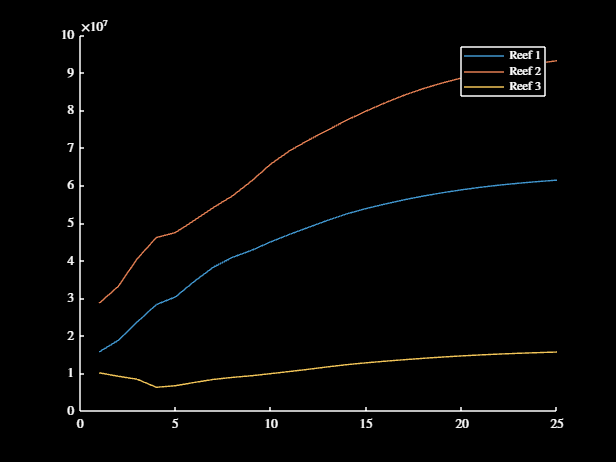

% calculate and plot the larval contributions
larvalContMat = calcLarvalContrib(popMat, specStruct.fecundVec, conMat);
figure
hold on
for i = 1:size(larvalContMat, 1)
    plot(larvalContMat(i, :)', 'Color', getColour(i))
end
legend("Reef 1", "Reef 2", "Reef 3")
darkFig()


% for a test, let's look at the populations of each reef, along with their
% larval output
specStruct.weightVec = [1, 1.2, 1.5, 2];
var1 = calcBiomass(popMat, specStruct.weightVec);
var2 = mean(var1, 2)

var2 = 1.0e+03 *

    1.6931
    1.3941
    0.6447


var3 = sum(conMat, 2)

var3 =     0.1700
    0.3100
    0.1100



% yep, it looks like to me that the above calculations are reasonable

% let's do a very obvious case, just to make 100% sure that it is all
% working as intended
conMat = 0.25 * ones(3, 3);
class(conMat)

ans = 'double'

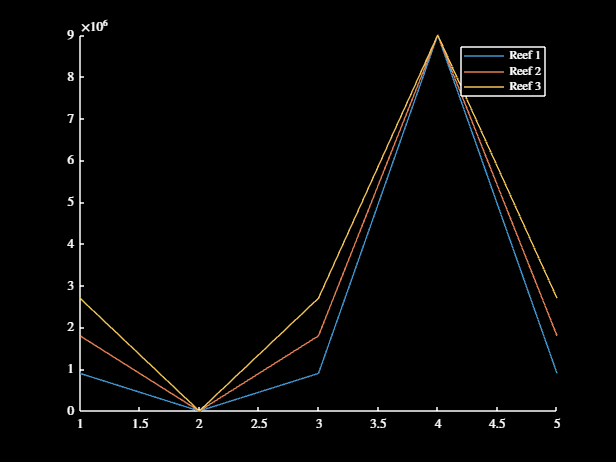

popMat = zeros(3, 4, 5);
popMat(1, :, :) = 1;
popMat(2, :, :) = 2;
popMat(3, :, :) = 3;
popMat(:, :, 2) = 0;
popMat(:, :, 4) = 10;
larvalContMat = calcLarvalContrib(popMat, specStruct.fecundVec, conMat);
figure
hold on
for i = 1:size(larvalContMat, 1)
    plot(larvalContMat(i, :)', 'Color', getColour(i))
end
legend("Reef 1", "Reef 2", "Reef 3")
darkFig()


% this seems pretty ok methinks

% gonna run the larval contribution sims then methinks, maybe will rq test
% them with just 5 runs each I suppose maybe idfk

## Final Experiments: Larval Contribution MPT, Mean and Recent Historical Values

% wanna quickly test that the matrices in the GBR set are in the same order
% as the matrices in the subsets, to ensure that the larval contribution
% methods actually work

% do some bullshit to find out
var1 = zeros(3, 30);
for i = 1:30
    var1(1, i) = sum(sum(abs(areaStructGBR.conMats{i}(areaStructSwains.reefInds, ...
        areaStructSwains.reefInds) - areaStructSwains.conMats{i})));
    var1(2, i) = sum(sum(abs(areaStructGBR.conMats{i}(areaStructTowns.reefInds, ...
        areaStructTowns.reefInds) - areaStructTowns.conMats{i})));
    var1(3, i) = sum(sum(abs(areaStructGBR.conMats{i}(areaStructNorth.reefInds, ...
        areaStructNorth.reefInds) - areaStructNorth.conMats{i})));
end
sum(sum(var1))

ans = 0


% swag ok

% need to write the code in a sequential form first, check if it works, and
% then run it in parallel afterwards

% need to test the mean and final values here too
methodStruct.methodInd = "meanLarvCont";
methodStruct.fecundVec = specStructCT.fecundVec;
methodStruct.meanVarWeight = 0.75;
simOutCell = runMPASimulation(simStructFin, areaStructSwains, areaStructGBR, ...
    specStructCT, randStructFin, actionStructFin, methodStruct)

% so that I can run the shit below, gonna do a devious little move here
% simStructTrue = simStructFin;
% simStructFin = simStructFinTest;
% simStructFin = simStructTrue;

% run the experiment for the Swains region

% ensure parallel processes are cancelled
if exist('futureVecFinSwains', 'var')
    cancelFutureVec(futureVecFinSwains);
    clear futureVecFinSwains
end

All futures finished or cancelled.



% run in parallel
methodStringVec = ["MPTLarvCont", "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", ...
    "MPTLarvCont", "finalBiom", "finalLarvCont", "meanBiom", "meanLarvCont"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 0, 0, 0, 0];
for i = 1:9
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinSwains(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructSwains, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
if checkFutureVec(futureVecFinSwains)
    for i = 1:9
        simOutCellSwains2{i} = fetchOutputs(futureVecFinSwains(i));
    end
    clear futureVecFinSwains
end

Futures have completed succesfully.


% run the experiment for the Towns region

% ensure parallel processes are cancelled
if exist('futureVecFinTowns', 'var')
    cancelFutureVec(futureVecFinTowns);
    clear futureVecFinTowns
end

All futures finished or cancelled.



% run in parallel
methodStringVec = ["MPTLarvCont", "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", ...
    "MPTLarvCont", "finalBiom", "finalLarvCont", "meanBiom", "meanLarvCont"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 0, 0, 0, 0];
for i = 1:9
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinTowns(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructTowns, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
if checkFutureVec(futureVecFinTowns)
    for i = 1:9
        simOutCellTowns2{i} = fetchOutputs(futureVecFinTowns(i));
    end
    clear futureVecFinTowns
end

Futures have completed succesfully.


% run the experiment for the North region

% ensure parallel processes are cancelled
if exist('futureVecFinNorth', 'var')
    cancelFutureVec(futureVecFinNorth);
    clear futureVecFinNorth
end

All futures finished or cancelled.



% run in parallel
methodStringVec = ["MPTLarvCont", "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", ...
    "MPTLarvCont", "finalBiom", "finalLarvCont", "meanBiom", "meanLarvCont"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 0, 0, 0, 0];
for i = 1:9
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinNorth(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructNorth, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
if checkFutureVec(futureVecFinNorth)
    for i = 1:9
        simOutCellNorth2{i} = fetchOutputs(futureVecFinNorth(i));
    end
    clear futureVecFinNorth
end

Futures have completed succesfully.


% save the second batch of experiments
save secondSetResults.mat simOutCellSwains2 simOutCellTowns2 simOutCellNorth2

% also save the workspace once over in general because I'm scared
save matlabHonoursCopy7-10-23.mat

% let's consolidate the results from the first two experiments here, I'm
% too scared to do it in the above for loops
% for i = 1:9
%     simOutCellSwains{7 + i} = simOutCellSwains2{i};
%     simOutCellTowns{7 + i} = simOutCellTowns2{i};
%     simOutCellNorth{7 + i} = simOutCellNorth2{i};
% end

clear simOutCellSwains2 simOutCellTowns2 simOutCellNorth2

% note that as I realised previously, the mean larval contribution and mean
% biomass are redundant, so I'm going to remove them from the solution
% structures here
% simOutCellSwains{15}.methodStruct.methodInd
% simOutCellSwains{16}.methodStruct.methodInd
% simOutCellTowns{15}.methodStruct.methodInd
% simOutCellTowns{16}.methodStruct.methodInd
% simOutCellNorth{15}.methodStruct.methodInd
% simOutCellNorth{16}.methodStruct.methodInd
% simOutCellSwains = simOutCellSwains(1:14);
% simOutCellTowns = simOutCellTowns(1:14);
% simOutCellNorth = simOutCellNorth(1:14);

% make sure that worked xd
% for i = 1:length(simOutCellSwains)
%     simOutCellSwains{i}.methodStruct.methodInd
% end

% I'm also going to reorder the solutions now too heehe
% var1 = [2, 1, 13, 14, 3:7, 8:12];
% simOutCellSwains = simOutCellSwains(var1);
% simOutCellTowns = simOutCellTowns(var1);
% simOutCellNorth = simOutCellNorth(var1);

% make sure that worked xd
for i = 1:length(simOutCellSwains)
    simOutCellSwains{i}.methodStruct.methodInd
end

ans = "none"

ans = "random"

ans = "finalBiom"

ans = "finalLarvCont"

ans = "MPTBiom"

ans = "MPTBiom"

ans = "MPTBiom"

ans = "MPTBiom"

ans = "MPTBiom"

ans = "MPTLarvCont"

ans = "MPTLarvCont"

ans = "MPTLarvCont"

ans = "MPTLarvCont"

ans = "MPTLarvCont"

simOutCellSwains{4}

ans = struct with fields:
             mpaSel: {100×1 cell}
         objFuncTot: [100×1 double]
          objFuncTS: {100×1 cell}
      objFuncExpVal: [100×1 double]
         objFuncVar: [100×1 double]
    objFuncTotRetro: [100×1 double]
     objFuncTSRetro: {100×1 cell}
           exitFlag: [100×1 double]
       methodStruct: [1×1 struct]


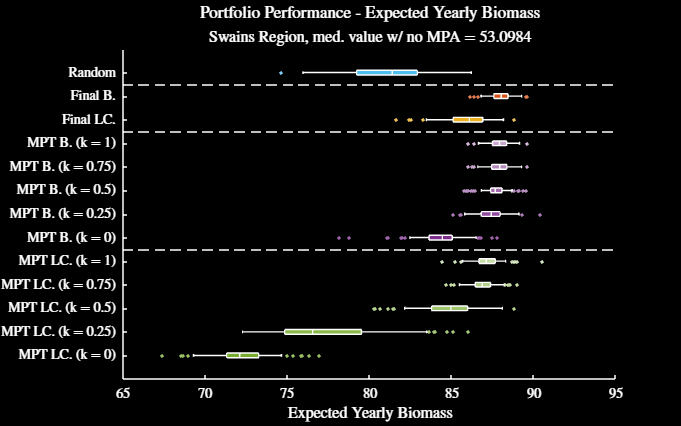

% now, plot the results
figure
plotMethodPerf(simOutCellSwains, "expVal", "Swains", false)
setFontSize(12)
figResize(1, 1.2)
saveFig("portPerfExpSwains")
plotMethodPerf(simOutCellSwains, "expVal", "Swains", true)
darkFig()
setFontSize(12)
saveFig("portPerfExpSwainsDM")

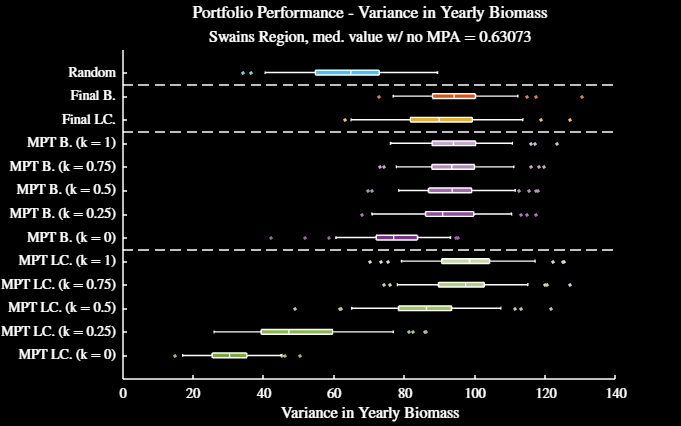

figure
plotMethodPerf(simOutCellSwains, "var", "Swains", false)
setFontSize(12)
figResize(1, 1.2)
saveFig("portPerfVarSwains")
plotMethodPerf(simOutCellSwains, "var", "Swains", true)
darkFig()
setFontSize(12)
saveFig("portPerfVarSwainsDM")

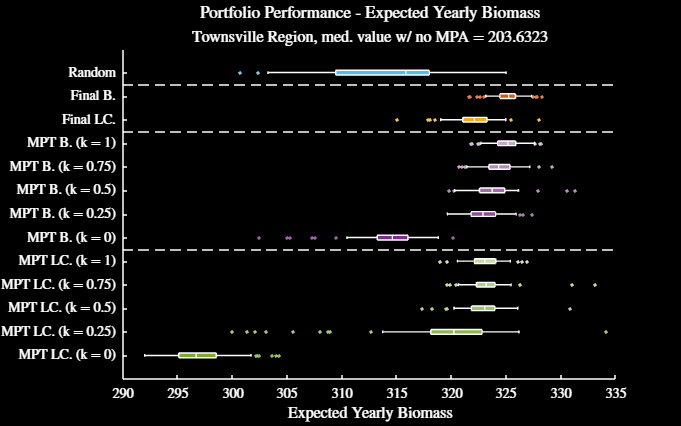

figure
plotMethodPerf(simOutCellTowns, "expVal", "Townsville", false)
setFontSize(12)
xlim([290, 335])
figResize(1, 1.2)
saveFig("portPerfExpTowns")
plotMethodPerf(simOutCellTowns, "expVal", "Townsville", true)
xlim([290, 335])
darkFig()
setFontSize(12)
saveFig("portPerfExpTownsDM")

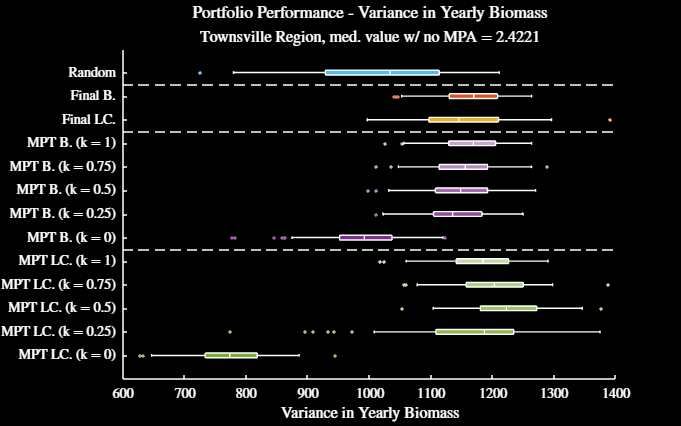

figure
plotMethodPerf(simOutCellTowns, "var", "Townsville", false)
setFontSize(12)
xlim([600, 1400])
figResize(1, 1.2)
saveFig("portPerfVarTowns")
plotMethodPerf(simOutCellTowns, "var", "Townsville", true)
xlim([600, 1400])
darkFig()
setFontSize(12)
saveFig("portPerfVarTownsDM")

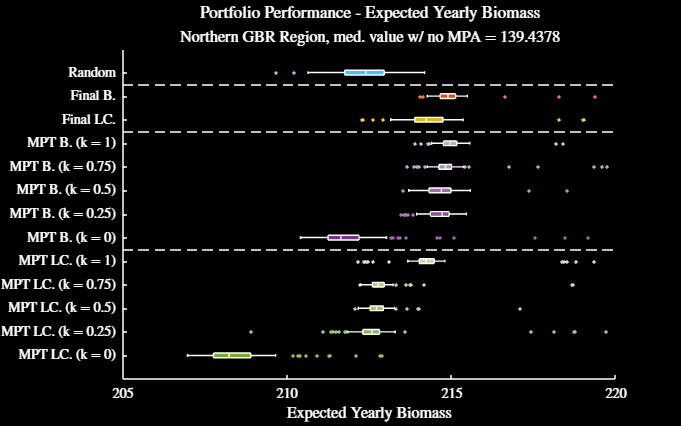

figure
plotMethodPerf(simOutCellNorth, "expVal", "Northern GBR", false)
setFontSize(12)
xlim([205, 220])
figResize(1, 1.2)
saveFig("portPerfExpNorth")
plotMethodPerf(simOutCellNorth, "expVal", "Northern GBR", true)
darkFig()
setFontSize(12)
xlim([205, 220])
saveFig("portPerfExpNorthDM")

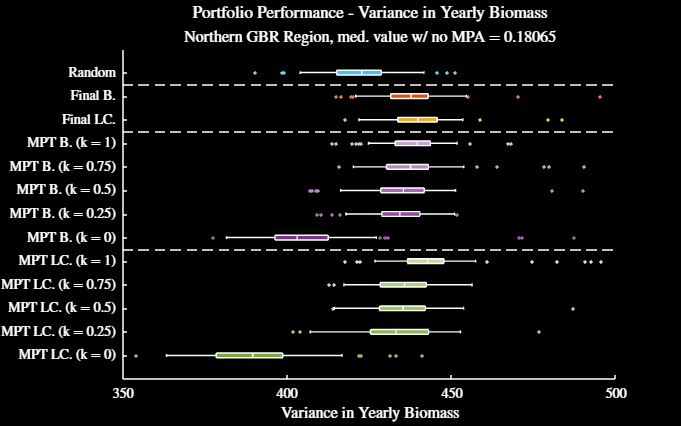

figure
plotMethodPerf(simOutCellNorth, "var", "Northern GBR", false)
setFontSize(12)
xlim([350, 500])
figResize(1, 1.2)
saveFig("portPerfVarNorth")
plotMethodPerf(simOutCellNorth, "var", "Northern GBR", true)
darkFig()
setFontSize(12)
xlim([350, 500])
saveFig("portPerfVarNorthDM")